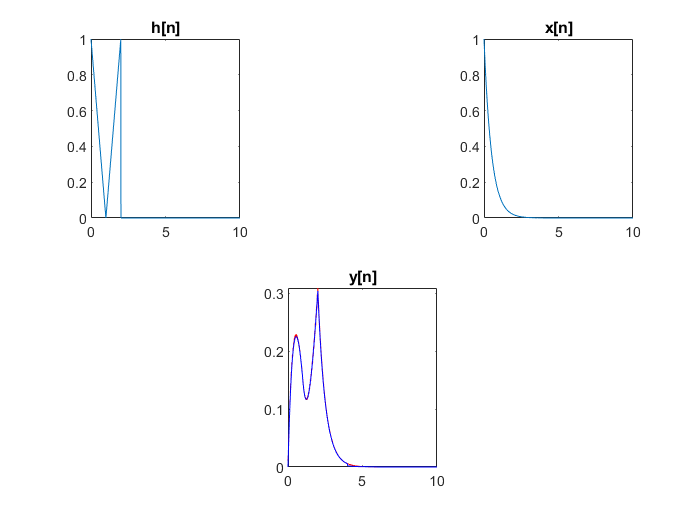

clc
clear
close all

t=0:0.01:10;
h=h4(t);
subplot(2,3,1);plot(t,h);title('h[n]');
x=exp(-2*t).*(rect(t,0,4,1));
subplot(2,3,3);plot(t,x);title('x[n]');
tau=-6:0.01:20;
h1=h4(tau);
x1=exp(-2*tau).*(rect(tau,0,4,1));
for i=1:length(t)
    tt=t(i);
    x1_tt=exp(-2*(tt-tau)).*(rect((tt-tau),0,4,1));
    y_tt(i)=trapz(tau,x1_tt.*h1);
end 
subplot(2,3,5);
plot(t,y_tt,"Color",'r');title('y[n]');
hold on;
r=a5(t);plot(t,r,"Color",'b');